# Comparar datos agrupados utilizando diagramas de caja 

Este ejemplo muestra cómo comparar dos grupos de datos creando un diagrama de caja con muescas. Las muescas muestran la variabilidad de la mediana entre las muestras. El ancho de una muesca se calcula de manera que las cajas cuyas muescas no se superponen tienen medianas diferentes al nivel de significancia del 5%. El nivel de significancia se basa en la suposición de una distribución normal, pero las comparaciones de medianas son razonablemente robustas para otras distribuciones. Comparar las medianas en los diagramas de caja es como una prueba de hipótesis visual, análoga a la prueba t utilizada para las medias. Para obtener más información sobre las diferentes características de un diagrama de caja, consulta [Box Plot](docid:stats_ug#mw_712e4076-f8d1-4e11-bcf7-5f79da6fe537).

Carga el data set `fisheriris`. El conjunto de datos contiene mediciones de la longitud y el ancho de los sépalos y pétalos de tres especies de flores de iris. Almacena los datos del ancho del sépalo para las iris setosa como `s1`, y los datos del ancho del sépalo para las iris versicolor como `s2`

load fisheriris
s1 = meas(1:50,2);
s2 = meas(51:100,2);

Crea un diagrama de caja con muescas utilizando los datos de muestra y etiqueta cada caja con el nombre de la especie de iris que representa.

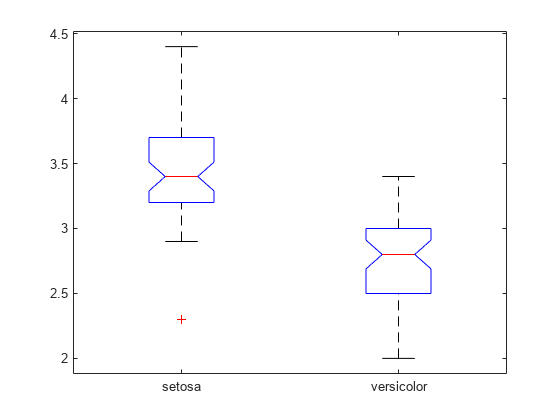

boxplot([s1 s2],'Notch','on', ...
        'Labels',{'setosa','versicolor'})

Las muescas de las dos cajas no se superponen, lo que indica que las medianas de los anchos de los sépalos de las iris setosa y versicolor son significativamente diferentes al nivel de significancia del 5%. Ni la línea roja de la mediana en la caja de la setosa ni la línea roja de la mediana en la caja de la versicolor parecen estar centradas dentro de sus respectivas cajas, lo que indica que cada muestra está ligeramente sesgada. Además, los datos de la setosa contienen un valor atípico, mientras que los datos de la versicolor no contienen ningún valor atípico.

Instead of using the `boxplot` function, you can use the `boxchart` MATLAB® function to create box plots. Recreate the previous plot by using the `boxchart` function rather than `boxplot`.

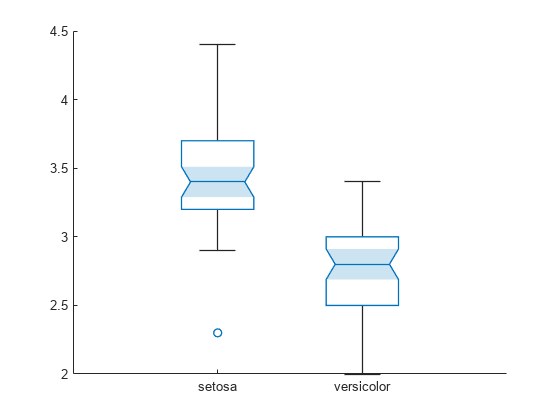

speciesName = categorical(species(1:100));
sepalWidth = meas(1:100,2);
b = boxchart(speciesName,sepalWidth,'Notch','on');

Each notch created by `boxchart` is a tapered, shaded region around the median line. The shading helps to better identify the notches.

One advantage of using `boxchart` is that the function creates a `BoxChart` object, whose properties you can change easily by using dot notation. For example, you can alter the style of the whiskers by specifying the `WhiskerLineStyle` property of the object `b`.

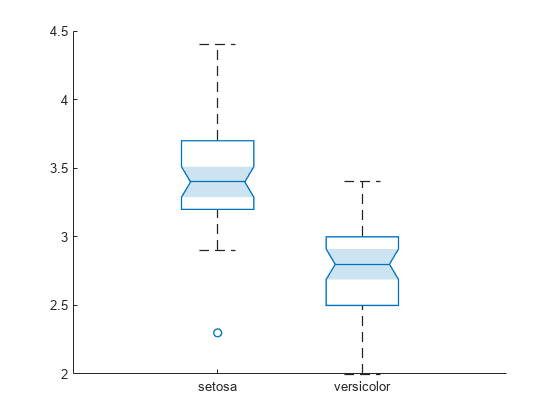

b.WhiskerLineStyle = '--';

For more information on the advantages of using `boxchart`, see [Alternative Functionality](docid:stats_ug#mw_c2e3616d-49fc-40af-80f9-c6655ccf8f8b).

*Copyright 2012 The MathWorks, Inc.*